# ECEN 611 Homework 4: Gap Function and Mutual Inductance for Salient Pole Rotor 

## Problem 2

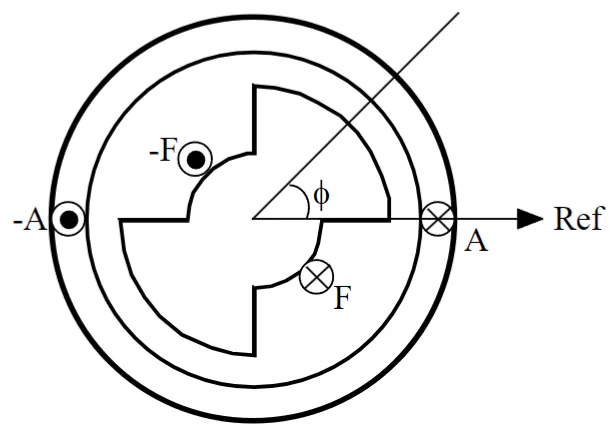

(pole arc = 90 degree)

clearvars 
clc 

### Inverse Gap Function 

*if you could make Problem 1 a function...* 

syms g_min g_max     positive real
syms alpha           positive real 
syms phi                      real 
syms g_phi(phi)
syms theta_r theta 

assume( (alpha > 0) & (alpha <= deg2rad(180)) )

T = 2*pi;
POLEARC = deg2rad(90);
THETA_R = deg2rad(45);

poleArc = alpha;
midArc = T/2 - poleArc;

rotor_profile_theta = [poleArc/2 midArc poleArc midArc poleArc/2];
rotor_profile_turning_phi = [theta_r, theta_r + cumsum(rotor_profile_theta)];

rotor_profile_turning_phi = subs( ...
    rotor_profile_turning_phi, ...
    poleArc, POLEARC ...
)

$$rotor\_profile\_turning\_phi = \left(\begin{array}{cccccc} \theta_{r} & \theta_{r}+\frac{\pi }{4} & \theta_{r}+\frac{3\,\pi }{4} & \theta_{r}+\frac{5\,\pi }{4} & \theta_{r}+\frac{7\,\pi }{4} & \theta_{r}+2\,\pi \end{array}\right)$$

phi_ref = 0;
rotor_profile_turning_phi = [phi_ref, rotor_profile_turning_phi]

$$rotor\_profile\_turning\_phi = \left(\begin{array}{ccccccc} 0 & \theta_{r} & \theta_{r}+\frac{\pi }{4} & \theta_{r}+\frac{3\,\pi }{4} & \theta_{r}+\frac{5\,\pi }{4} & \theta_{r}+\frac{7\,\pi }{4} & \theta_{r}+2\,\pi \end{array}\right)$$

gap_profile = [g_min, g_max, g_min, g_max, g_min];

firstPhi = rotor_profile_turning_phi(1);
secondPhi = rotor_profile_turning_phi(2);

firstGap = gap_profile(1);

g_phi(phi) = piecewise(firstPhi <= phi < secondPhi, firstGap)

$$g\_phi(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi <\theta_{r}\wedge 0\leq \varphi \end{array}\right.$$


for k = 2 : length(rotor_profile_turning_phi) - 1 

    thisPhi = rotor_profile_turning_phi(k);
    nextPhi = rotor_profile_turning_phi(k+1); 
    thisGap = gap_profile(k);

    g_phi(phi) = piecewise( ...
        thisPhi <= phi < nextPhi, thisGap, ...
        phi <= thisPhi, g_phi(phi) ...
    ); 
end  

Index exceeds the number of array elements. Index must not exceed 5.

Error in indexing (line 962)
                R_tilde = builtin('subsref',L_tilde,Idx);


g_phi(phi) = simplify(g_phi)
g_phi_inv = 1 / g_phi

g_phi_inv_ext(phi) = piecewise( ...
    -2*T <= phi < -T, g_phi_inv(phi+2*T), ...
    -T <= phi < 0, g_phi_inv(phi+T), ...
    0 <= phi < T, g_phi_inv(phi), ...
    T <= phi <= 2*T, g_phi_inv(phi-T) ...
)
vars = [poleArc g_min g_max theta_r];
VALS = [POLEARC 0.5   0.8   THETA_R];

figure 
fplot(subs(g_phi_inv, vars, VALS), [-3*T 3*T], ...
      "DisplayName", "Original Inverse Gap Function", ...
      "LineWidth", 1.2)
hold on
fplot(subs(g_phi_inv_ext, vars, VALS), [-3*T 3*T], ...
      "DisplayName", "Extended Inverse Gap Function", ...
      "LineStyle",":", ...
      "LineWidth", 1.2 ...
      )
hold off 
ylim([0 2.5])
grid on 
legend 
ax = gca;
S = sym(ax.XLim(1):pi/2:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

### (a) Magnetizing inductance of winding A on the stator

### (b) Magnetizing inductance of winding F on the rotor

### (c) Mutual inductance between stator and rotor for the following salient pole synchronous machine 